## ALL INDIVIDUAL ANALYSES BEYOND 'EARLY ANALYSIS' (GROUP & IND VARS)

CRF & DRF 

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% all VIS AREAS
% all STIM CONDs

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for all trials'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear recomboOnePtAllFramesAllTrialMinusMeanBase
    clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
    % collect all trials over all frames for the ith point
    clear onePtAllFramesAndTrials % new var each point
    onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); 
    onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
    % for every trace, subtract the baseline value at that point from each frame value
    clear tr % for each trial in onePtAllFramesAndTrial
    for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
        % getting TRIAL VECTOR
        clear onePtAllFramesOneTrial % make new var for each trial
        % index into each trace/vector & save as variable
        onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
        % getting MEAN BASEline VALUE for each TRIAL
        clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
        % collect 4 baseline frames for tr-th ith trial
        allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
        clear mean4baseFramesOnePtOneTrial
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
        mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
        % BASEline CORRECTion of TRIAL VECTOR
        % new baseline-corrected trace for each trial
        onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
        % collect CORRECTed TRIAL VECTORS in matrix
        % (only clear this outside the loop for each point)
        recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
        % plot one baseline corrected trace at a time
        subplot(2,3,i) % make a subplot
        plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                
        hold on % hold for next trial
                
    end % end tr loop
      
    hold on % hold for plotting mean over subplot
        
    % get mean baselined trace across all trials
    meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
   
    plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',3)
    title(reigons{i})
        
    ylim([-0.25 0.25]) 
    xlim([1 length(x_axis)])
    ylabel('df/f')
    xlabel('frames')

    ax = gca;
    x.XTick = [1:1:length(x_axis)];
       
end % end i loop


% MEAN across TRIALS 
% all VIS AREAS
% per CONTRAST

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': df/f vs frames per contrast, \n averaged across trials'); % making char variables for sprintf/title later
%suptitle(sprintf('%s', date, subjName, titleText));
    
clear recomboOnePtAllFramesAllTrialMinusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear c
    for c = 1:length(uniqueContrasts) % for each contrast
                
        % TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
        % MEAN over trials
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
        % 1x # trials variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frame
                
        % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
        % trials and we already took the mean across trials
        clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
        % collect 4 baseline frames 
        allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
        clear mean4baseFramesOnePtOneCon
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneCon = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
        % BASEline CORRECTION
        % new baseline-corrected trace for each mean trace
        clear onePtOneConMinusMeanBase
        onePtOneConMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneCon;
        
        % COLLECT corrected traces in matrix
        % (only clear this each tine go thru i loop (new one each subplot)
        recomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = onePtOneConMinusMeanBase;
            
        % STDEV of deviation from the mean oover trials
         clear err
        % our mean trace is averaged over trials. We want to know how much the trials 
        % values varied, not how much the mean trial values vary over time...
        err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtOneConMinusMeanBase);
        subplot(2,3,i)
        errorbar(x_axis,onePtOneConMinusMeanBase,err,'linewidth',1)
        ylim([-0.02 0.1])  
        xlim([1 length(x_axis)])
        title(reigons{i})
        ylabel('df/f')
        xlabel ('frames')
        
        hold on % all contrast traces on one fig
                
    end % end c loop
            
hold on
legend(cons4Legend)
                
end % end i loop


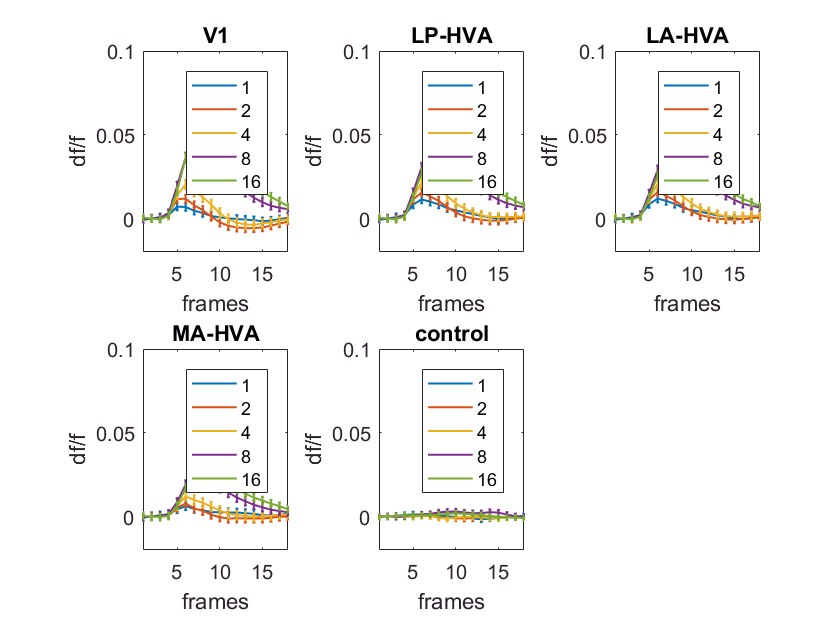

% MEAN across TRIALS 
% all VIS AREAS
% DURATION

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': df/f vs frames per duration, \n averaged across trials'); % making char variables for sprintf/title later
%suptitle(sprintf('%s', date, subjName, titleText));
    
clear recomboOnePtAllFramesAllTrialMinusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear d
    for d = 1:length(uniqueDurations) % for each contrast
                
        % TRIALS
        clear dthTrials
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        
        % MEAN over trials
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % creating a 
        % 1x # trials variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frame
                
        % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
        % trials and we already took the mean across trials
        clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
        % collect 4 baseline frames 
        allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
        clear mean4baseFramesOnePtOneDur
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneDur = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
        % BASEline CORRECTION
        % new baseline-corrected trace for each mean trace
        clear onePtOneDurMinusMeanBase
        onePtOneDurMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneDur;
        
        % COLLECT corrected traces in matrix
        % (only clear this each tine go thru i loop (new one each subplot)
        recomboOnePtAllFramesAllTrialMinusMeanBase(d,:) = onePtOneDurMinusMeanBase;
            
        % STDEV of deviation from the mean oover trials
         clear err
        % our mean trace is averaged over trials. We want to know how much the trials 
        % values varied, not how much the mean trial values vary over time...
        err = std(PTSdfof(i,:,dthTrials),[],3)/sqrt(sum(dthTrials)); % across all trials = 3rd dim
                
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,d) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtOneDurMinusMeanBase);
        subplot(2,3,i)
        errorbar(x_axis,onePtOneDurMinusMeanBase,err,'linewidth',1)
        ylim([-0.02 0.1])  
        xlim([1 length(x_axis)])
        title(reigons{i})
        ylabel('df/f')
        xlabel ('frames')
        
        hold on % all contrast traces on one fig
                
    end % end d loop
            
hold on
legend(durs4Legend)
                
end % end i loop

% DRF
% peak frames defined earlier

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': duration response function'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

yMax = 0.2;

clear i
for i = 1:length(xPickedPts) % for each point
  
    clear durStdErr
    clear drf
    clear DRFminusMeanBase
    
    clear d
    for d = 1:length(uniqueDurations) 
                
        % TRIALS
        clear dthTrials
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        
        % calculate CRF
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by # trials
        clear sq5FramesOverTrialsPTSdfof
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,dthTrials));
        % take the mean over frames, returns 1 x # trials
        clear meanOverFramesSq5FramesOverTrialsPTSdfof
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        % collect each c-th CRF value for this point
        drf(d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % GET mean BASEline
        % the baseline for each CRF value is the mean of the baseline frames for
        % the ith point and cth contrast
        % get all frames & cth trials
        clear baselineFramesIthPtDthTrials
        baselineFramesIthPtDthTrials = squeeze((PTSdfof(i,baselineIdx,cthTrials)));
        % now have baseline frames x trials
        % take mean across trials 
        clear  meanBaselineFramesIthPtDthTrial
        meanBaselineFramesIthPtDthTrials = mean(baselineFramesIthPtDthTrials,2);
        % take mean across frames
        meanBaselineFramesIthPtDthTrials = mean(meanBaselineFramesIthPtDthTrials,1);
            
        % do BASEline CORRECTION
        % subtract the cth baseline from the flourescence at each c
        DRFminusMeanBase(d) = drf(d)-meanBaselineFramesIthPtDthTrials; % clear this var in between subplots

        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
        clear stdErr
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
        durStdErr(1,d) = stdErr; % clear outside i loop
        
    end % end contrast loop - have full baselined CRF for ith point
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,3,i)
    % 7 contrasts for x axis
    x_axis = 1:length(uniqueDurations);
    drfChart = errorbar(x_axis,DRFminusMeanBase,durStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    
    title(reigons{i})
    ylim([-0.01 yMax]) 
    xlim([min(x_axis), max(x_axis)])

%     set(gca,'xtick',1:5); 
%     set(gca,'xticklabel',durs4Axes);
    
    ylabel('df/f')
    xlabel('duration (ms)')
            
end % end i loop


% CRF for each DURATION - LOG
% all VIS AREAS

figure 
clear titleText
titleText = sprintf(': CRF for each duration'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,cthDthTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('contrast (%)')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Legend)
    
end % end i loop


CRF by RUN SPEED ** (2 THRESHOLDS) **

% PIVK HI & LOW RUN TRIALS
lowRunThresh = 60
hiRunThresh = 60
[meanSpeedAllTrials,idxHiRunTrials,idxLowRunTrials] = calcMeanRunSpeedAllTrials_excludeMiddle(allStop,allResp,lowRunThresh,hiRunThresh)

% FILTER first and last few trials... can change num trials in code
[runIdxOnsetsMeetsCriteria,meanSpeedAllTrials] = filterOnsets_removeEarlyAndLateTrials(meanSpeedAllTrials,earliestTrial,numLateTrialsSubtract);
sizemeanSpeedAllTrials = size(meanSpeedAllTrials)

% STAT & RUN SAME PLOT

%durat = 6;
durat = 1:length(uniqueDurations);

yMax = 0.08;

figure 
clear titleText
titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

lineColors1 =  {'--k','--m','--c','--g','--b','--r'};
lineColors2 =  {'k','m','c','g','b','r'};
lineWides = [1,1];

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
        
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthLOWtrials
             idxCthDthLOWtrials = intersect(idxCthDthTrial,idxLowRunTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthLOWtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthLOWtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthLOWtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        %errorbar(x_axis,dthCRF,contStdErr,'-g','MarkerSize',3) 
        %errorbar(x_axis,dthCRF,contStdErr,lineColors(d),'MarkerSize',lineWides(1)) 
        plot(x_axis,dthCRF,lineColors1{d},'linewidth',lineWides(1))
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same butRUN

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthHitrials
             idxCthDthHiTrials = intersect(idxCthDthTrial,idxHiRunTrials); % idxLowRunTrials was made in runSpeed2 script
             
             % clear idxCthDthLOWtrials
             % idxCthDthLOWtrials = idxLowRunTrials(intersect(idxCthDthTrial,idxLowRunTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthHiTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthHiTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthHiTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        %errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3)
        %errorbar(x_axis,dthCRF,contStdErr,lineColors(d),'MarkerSize',lineWides(2)) 
        plot(x_axis,dthCRF,lineColors2{d},'linewidth',lineWides(2))
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on  
        
    end % end d loop
    
    legend(durs4Legend)

hold on
    
end % end i loop


% for non log

%         x_axis = uniqueContrasts;
%         errorbar(x_axis,dthCRF,contStdErr,'-g','MarkerSize',3) % -s seemed to get diff color for each dur?
%         title(reigons{i})
%         
%         ylim([-0.01 yMax]) 
%         xlim([min(x_axis), max(x_axis)])
% 
%         ylabel('df/f')
%         xlabel('contrast (%)')


CRF for RUN (1 thresh)

% CRF STAT & RUN SAME PLOT

%durat = 1:length(uniqueDurations);
durat = 1

durat = 1

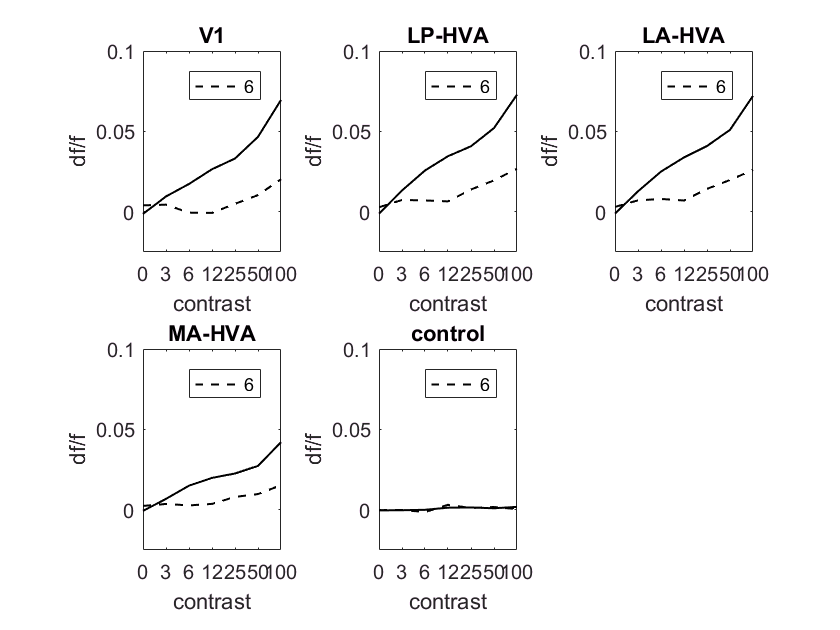


yMax = 0.1;

figure 
clear titleText
titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
%suptitle(sprintf('%s', date, subjName, titleText));

lineColors1 =  {'--k','--m','--c','--g','--b','--r'};
lineColors2 =  {'k','m','c','g','b','r'};
lineWides = [1,1];

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
        
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSTATtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSTATtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        %errorbar(x_axis,dthCRF,contStdErr,'-g','MarkerSize',3) 
        %errorbar(x_axis,dthCRF,contStdErr,lineColors(d),'MarkerSize',lineWides(1)) 
        plot(x_axis,dthCRF,lineColors1{d},'linewidth',lineWides(1))
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same butRUN

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthRUNtrials
             idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthRUNtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthRUNtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        %errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3)
        %errorbar(x_axis,dthCRF,contStdErr,lineColors(d),'MarkerSize',lineWides(2)) 
        plot(x_axis,dthCRF,lineColors2{d},'linewidth',lineWides(2))
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on  
        
    end % end d loop
    
    legend(durs4Legend)

hold on
    
end % end i loop

CRF for PUPIL

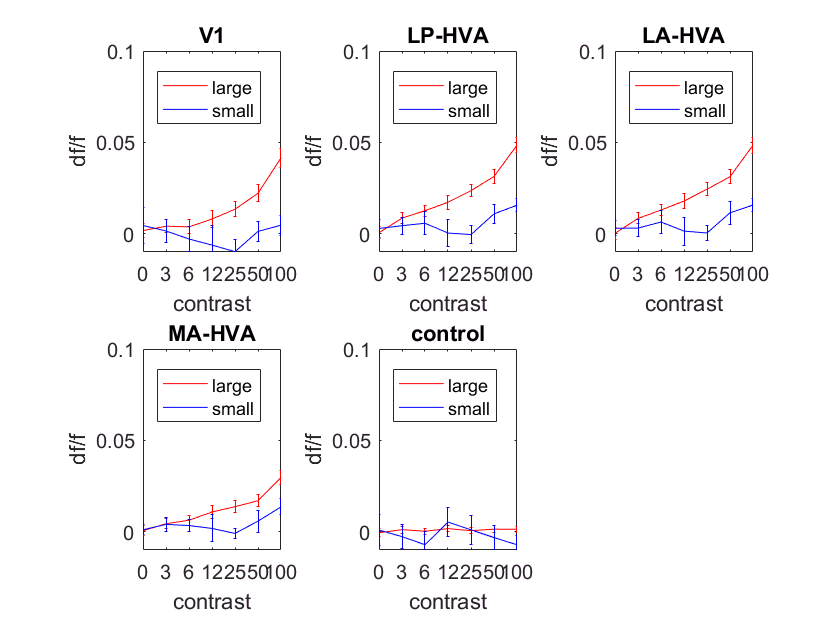

% small & large SAME PLOT

yMax = 0.1;
yMin = -0.01;

figure 
clear titleText
%titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
%suptitle(sprintf('%s', date, subjName, titleText))

durat = 1; 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = durat
    %for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxLowRunTrials); % idxLowRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthLARGEpupTrials = intersect(idxCthDthTrial,idxLargePupilTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthLARGEpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthLARGEpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthLARGEpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-r','MarkerSize',3) 
        title(reigons{i})
        
        %ylim([-0.025 0.01]) 
        %xlim([0, 8])
        ylim([yMin yMax]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same but 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = durat
   % for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthSMALLtrials
             idxCthDthSMALLpupTrials = intersect(idxCthDthTrial,idxSmallPupilTrials); % idxLowRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxLowRunTrials(intersect(idxCthDthTrial,idxLowRunTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSMALLpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSMALLpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSMALLpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3) 
        title(reigons{i})
        
        ylim([yMin yMax]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend('large','small')
    
end % end i loop